# Allocating Resources After a Major Weather Event

## Table of contents:

- **Background and Scope**

- **Visualisation**

- **Analysis**

The analysis was done based on Storm Data for year 2017. The analysis was done on various parameters including The total damage and Counties.

## Background and Scope

### Import the Data

alldata=importfile("StormEvents_2017_finalProject.csv");

alldata= alldata(alldata.Begin_Date_Time >= '2017-08-17 00:00:00' & alldata.Begin_Date_Time < '2017-09-03 23:23:01',:);
alldata.Crop_Cost(isnan(alldata.Crop_Cost))=0;
alldata.Property_Cost(isnan(alldata.Property_Cost))=0;
alldata.totalcost= alldata.Property_Cost + alldata.Crop_Cost;

mostevent =groupsummary (alldata,'State','sum',"totalcost");

mostevent = sortrows(mostevent,'sum_totalcost','descend');
mostevent = mostevent(ismember(mostevent.State,{'ARKANSAS','KENTUCKY','LOUISIANA','MISSISSIPPI','NORTH CAROLINA','TENNESSEE','TEXAS'}),:);

### Two States Most Impacted by Harvey

Texas and Louisiana

Moststate =mostevent.State(1)

Moststate = categorical
     TEXAS 


secondMost= mostevent.State(2)

secondMost = categorical
     LOUISIANA 


### Table of Events for Two Most Impacted States

Create and display a few rows of events that include only the two most affected states

Twostates = alldata(ismember(alldata.State,{'LOUISIANA','TEXAS'}),:)

Twostates = 361×25 table
    EpisodeID      Event_ID     State    Year    Month        Event_Type          CZ_Name        Begin_Date_Time      Timezone       End_Date_Time       Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon                                                                                                                                                                                                                                                                       

## Visualizations

### Figure of Event Types

Create a figure showing the type and number of occurances for events related to Harvey in the two states

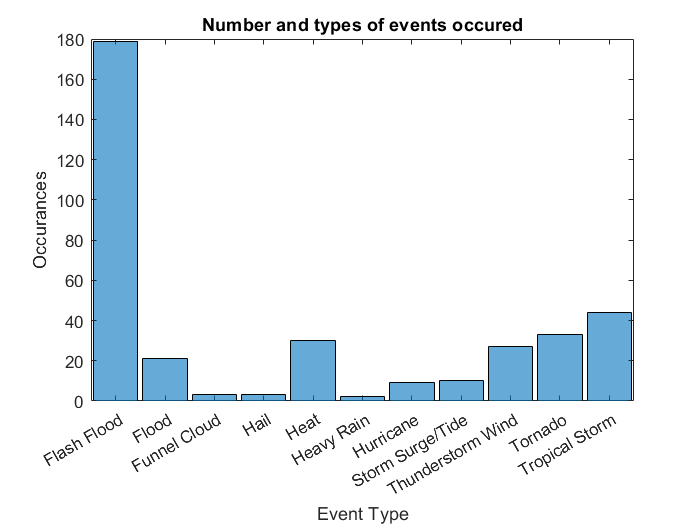

Twostates.Event_Type = removecats(Twostates.Event_Type,{'Astronomical Low Tide','Avalanche','Blizzard','Coastal Flood','Cold/Wind Chill','Debris Flow','Dense Fog','Dense Smoke','Drought','Dust Devil','Dust Storm','Excessive Heat','Extreme Cold/Wind Chill','Waterspout','Wildfire','Winter Storm','Winter Weather','Tropical Depression','Strong Wind','Ice Storm','Lake-Effect Snow','Lakeshore Flood','Lightning','Marine Hail','Marine High Wind','Marine Hurricane/Typhoon','Marine Strong Wind','Marine Thunderstorm Wind','Marine Tropical Depression','Marine Tropical Storm','Rip Current','Sleet','Sneakerwave','Freezing Fog','Frost/Freeze','Heavy Snow','High Wind','High Surf'});
histogram(Twostates.Event_Type);

title('Number and types of events occured')
xlabel('Event Type')
ylabel('Occurances')

### Figure of Event Locations

Show the location of events in the two states. Be sure to use different markers for the two states

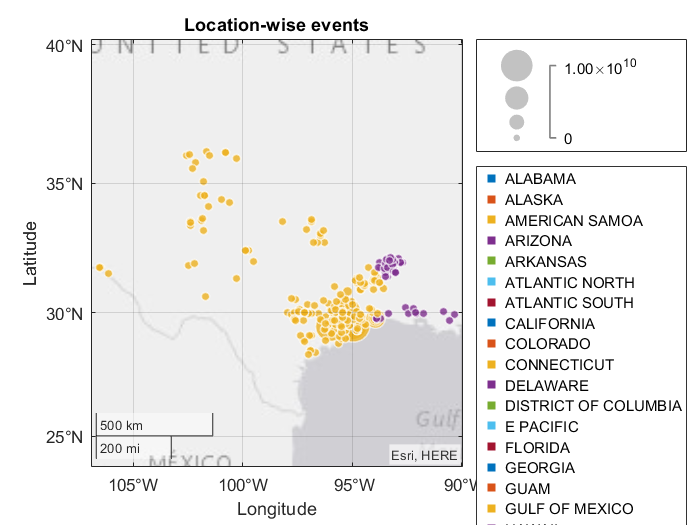

MostData = alldata(alldata.State == 'TEXAS'|alldata.State == 'LOUISIANA',:);
geobubble(MostData.Begin_Lat,MostData.Begin_Lon,MostData.totalcost,MostData.State);

legend show

title('Location-wise events')

## Analysis

### Three Counties with Most Events in State 1

Either type out, show in a table, or show in a clear visualization the three counties with the most events in state 1.

State1 = Twostates(Twostates.State == 'TEXAS',:);
State2 = Twostates(Twostates.State == 'LOUISIANA',:);
County1= groupsummary(State1,"CZ_Name");
County1 = sortrows(County1,'GroupCount','descend')

County1 = 95×2 table
     CZ_Name      GroupCount
    __________    __________

    HARRIS            21    
    GALVESTON         17    
    FORT BEND         13    
    ANGELINA          12    
    BRAZORIA          12    
    SABINE            12    
    BASTROP            9    
    CHAMBERS           8    
    CALDWELL           7    
    MONTGOMERY         6    
    CALHOUN            5    
    JEFFERSON          5    
    MATAGORDA          5    
    WHARTON            5    
    FAYETTE            4    
    LIBERTY            4    


### Three Counties with Most Events in State 2

Either type out, show in a table, or show in a clear visualization the three counties with the most events in state 2.

County2= groupsummary(State2,"CZ_Name");
County2 = sortrows(County2,'GroupCount','descend')

County2 = 30×2 table
      CZ_Name       GroupCount
    ____________    __________

    NATCHITOCHES        21    
    SABINE              15    
    RED RIVER            9    
    WINN                 6    
    CAMERON              4    
    VERMILION            4    
    DE SOTO              3    
    UNION                2    
    ACADIA               1    
    BEAUREGARD           1    
    BIENVILLE            1    
    BOSSIER              1    
    CADDO                1    
    CALCASIEU            1    
    CALDWELL             1    
    CLAIBORNE            1    


### Three Counties with Highest Property Cost in State 1

Either type out, show in a table, or show in a clear visualization the three counties with the highest reported property cost in state 1. *Be sure to include the dollar amount*. 

CountyWH1= groupsummary(State1,"CZ_Name",'sum',"totalcost");
CountyWH1 = sortrows(CountyWH1,'sum_totalcost','descend')

CountyWH1 = 95×3 table
      CZ_Name       GroupCount    sum_totalcost
    ____________    __________    _____________

    GALVESTON           17              2e+10  
    FORT BEND           13         1.6004e+10  
    MONTGOMERY           6            1.4e+10  
    HARRIS              21         1.0001e+10  
    JEFFERSON            5              3e+09  
    BRAZORIA            12         2.0009e+09  
    ARANSAS              2           1.95e+09  
    ORANGE               3            1.5e+09  
    NUECES               2            1.3e+09  
    WALKER               4            1.2e+09  
    LIBERTY              4              1e+09  
    SAN JACINTO          3         7.0001e+08  
    HARDIN               1              6e+08  
    POLK                 2              6e+08  
    REFUGIO              3         5.2002e+08  
    SAN PATRICIO         2           5.07e+08  


### Three Counties with Highest Property Cost in State 2

Either type out, show in a table, or show in a clear visualization the three counties with the highest reported property cost in state 2. *Be sure to include the dollar amount*. 

CountyWH2= groupsummary(State2,"CZ_Name",'sum',"totalcost");
CountyWH2 = sortrows(CountyWH2,'sum_totalcost','descend')

CountyWH2 = 30×3 table
      CZ_Name       GroupCount    sum_totalcost
    ____________    __________    _____________

    CALCASIEU           1              6e+07   
    BEAUREGARD          1            1.5e+07   
    ACADIA              1              2e+05   
    CAMERON             4              72000   
    VERMILION           4               5000   
    BIENVILLE           1                  0   
    BOSSIER             1                  0   
    CADDO               1                  0   
    CALDWELL            1                  0   
    CLAIBORNE           1                  0   
    DE SOTO             3                  0   
    EAST CAMERON        1                  0   
    GRANT               1                  0   
    IBERIA              1                  0   
    JACKSON             1                  0   
    LA SALLE            1                  0   


## Conclusions and Recommendations

The most Affected States are Texas and Louisiana. The most affected counties based on events are Harris, Galveston, Angelina from Texas. Natchitoces, Sabine, Red River from LOUISIANA.The most affected counties based on Total cost are Galveston, Forest Bend and Montgomery from Texas. Calcasieu, Beauregard, Acadia from LOUISIANA.

These places are needed immidiate attention and should be priotized. The Galveston is the most affected county in Texas in both aspects. Also it constitute most of the cost incurred.